**Compute the VaR Using the Historical Simulation Method**

Unlike the normal distribution method, the historical simulation (HS) is a nonparametric method. It does not assume a particular distribution of the asset returns. Historical simulation forecasts risk by assuming that past profits and losses can be used as the distribution of profits and losses for the next period of returns. The VaR "today" is computed as the  *p* th-quantile of the last  *N* returns prior to "today."

Data = load('PortfolioReturns.mat');
Returns = Data.Returns;
DateReturns = Data.DateReturns;
Confidence = [95 99];
EstimationWindowSize = 250;

SampleSize = length(Returns);
TestWindowStart      = find(year(DateReturns)==1996,1);
TestWindow           = TestWindowStart : SampleSize;


For a VaR confidence level of 95% and 99%, set the complement of the VaR level.

pVaR = 1 - Confidence/100;

## Compute the VaR Using the Historical Simulation Method

Unlike the normal distribution method, the historical simulation (HS) is a nonparametric method. It does not assume a particular distribution of the asset returns. Historical simulation forecasts risk by assuming that past profits and losses can be used as the distribution of profits and losses for the next period of returns. The VaR "today" is computed as the  *p* th-quantile of the last  *N* returns prior to "today."

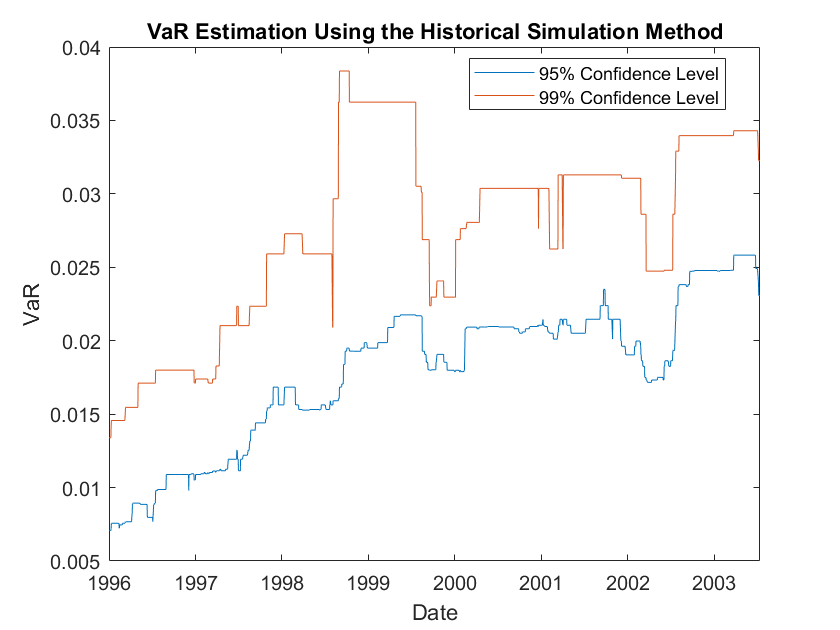

Historical95 = zeros(length(TestWindow),1);
Historical99 = zeros(length(TestWindow),1);

for t = TestWindow
    i = t - TestWindowStart + 1;
    EstimationWindow = t-EstimationWindowSize:t-1;
    X = Returns(EstimationWindow);
    Historical95(i) = -quantile(X,pVaR(1)); 
    Historical99(i) = -quantile(X,pVaR(2)); 
end

HistVar = [Historical95 Historical99];

figure;
plot(DateReturns(TestWindow),HistVar)
ylabel('VaR')
xlabel('Date')
legend(Confidence + "% Confidence Level","Location","Best")
title('VaR Estimation Using the Historical Simulation Method')